Experimento 1

format default

Resultats experimentals

Resultats1 = readtable("Resultados_IA.xlsx", "Sheet","Experiment 1");

Resultats1

Resultats1 = 11×5 table
       Seed       MourePrincipi_Distancia_    MoureFinal_Distancia_    MourePrincipi_Temps_    MoureFinal_Temps_
    __________    ________________________    _____________________    ____________________    _________________

         10323             10039                       9919                     7160                  8516      
         72718             10772                      10707                     9062                  9530      
     1.109e+05             11362                      10876                     7891                 10143      
         31416             10868                      10614                     8397                  8912      
      1.51e+05             10382                      10424                     7905                  7186      
     1.009e+05

Boxplots dels resultats

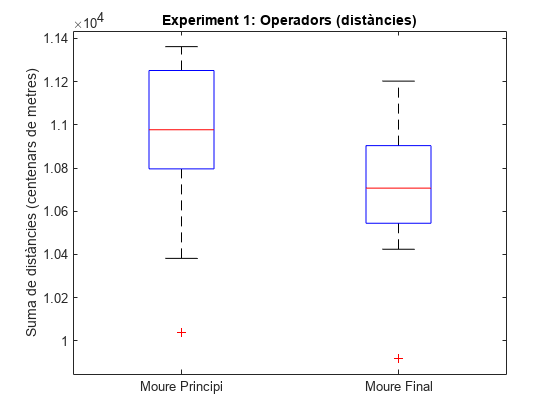

boxplot([Resultats1.MourePrincipi_Distancia_ Resultats1.MoureFinal_Distancia_], 'Labels',{'Moure Principi','Moure Final'})
title("Experiment 1: Operadors (distàncies)");
ylabel("Suma de distàncies (centenars de metres)");

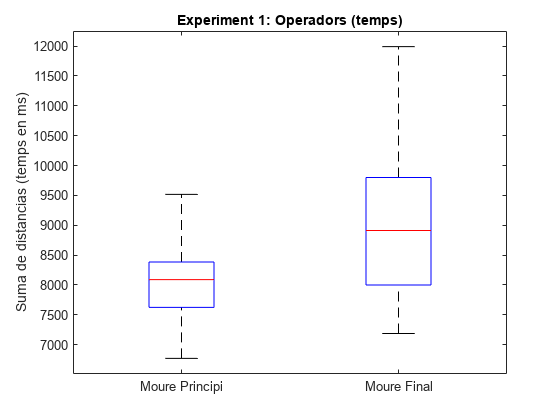


boxplot([Resultats1.MourePrincipi_Temps_ Resultats1.MoureFinal_Temps_], 'Labels',{'Moure Principi','Moure Final'})
title("Experiment 1: Operadors (temps)");
ylabel("Suma de distancias (temps en ms)");


mitjanes = [mean(Resultats1.MourePrincipi_Distancia_), mean(Resultats1.MoureFinal_Distancia_); mean(Resultats1.MourePrincipi_Temps_./1000) mean(Resultats1.MoureFinal_Temps_./1000)];
array2table(mitjanes, "VariableNames",{'Moure principi', 'Moure final'}, "RowNames", ["Suma de distàncies (centenars de metres)", "Temps (en s)"]);

t-test per comprobar les hipòtesis nules.

[h, p, ci, stats] = ttest(Resultats1.MourePrincipi_Distancia_, Resultats1.MoureFinal_Distancia_, "Alpha",0.05)

h = 1

p = 0.0028

ci =    95.2014
  343.3986


stats = struct with fields:
    tstat: 3.9374
       df: 10
       sd: 184.7231


[h2, p2, ci2, stats2] = ttest(Resultats1.MourePrincipi_Temps_ , Resultats1.MoureFinal_Temps_, "Alpha",0.05)

h2 = 1

p2 = 0.0277

ci2 = 1.0e+03 *

   -1.7159
   -0.1239


stats2 = struct with fields:
    tstat: -2.5750
       df: 10
       sd: 1.1849e+03


Experimento 2: Greedy vs Random

Resultats2 = readtable("Resultados_IA.xlsx", "Sheet","Experiment 2");

Resultats2

Resultats2 = 11×5 table
       Seed       GREEDY    RANDOMMitjanaDe5    TempsGreedy    TempsRandomMitjanaDe5
    __________    ______    ________________    ___________    _____________________

         10324    10656          10805             10886               10692        
         72719    10452          10572              7940                9301        
     1.109e+05    10667          10598              9921               11070        
         31417    10293          10272              8603               11636        
      1.51e+05    10903          11080              9342                9903        
     1.009e+05    10555          10769              9470               10618        
     2.012e+05    10834          11280             10613                9969        
         20903    10970          11041  


boxplot([Experimento2.GREEDY Experimento2.RANDOMMediaDe5], 'Labels',{'Greedy','Random'})

Unable to resolve the name 'Experimento2.GREEDY'.

title("Experimento 2: Estrategias de inicialización")
ylabel("Suma de distancias (centenares de metros)")

boxplot([Experimento2.TiempoGreedy Experimento2.TiempoRandomMediaDe5], 'Labels',{'Greedy','Random'})
title("Experimento 2: Estrategias de inicialización")
ylabel("Tiempo")

[h,p,~,stats] = ttest(Experimento2.GREEDY, Experimento2.RANDOMMediaDe5,"Tail","right")
[h,p,~,stats] = ttest(Experimento2.TiempoGreedy, Experimento2.TiempoRandomMediaDe5,"Tail","right")

Experimento 3: Lambda-Experimentación

Experimento3 

boxplot([Experimento3.VarName2, Experimento3.VarName3, Experimento3.VarName4], 'Labels',{'Medio','Uno', 'Dos'})
title("Experimento 3: Lambda del heurístico")
ylabel("Suma de distancias (centenares de metros)")

[h1,p1,~,stats] = ttest(Experimento3.VarName2, Experimento3.VarName3)
[h2,p2,~,stats] = ttest(Experimento3.VarName2, Experimento3.VarName4)
[h3,p3,~,stats] = ttest(Experimento3.VarName3, Experimento3.VarName4)

Experimento 4: Guerra de los Heurísticos

Experimento4 = ResultadosIA7S3

boxplot([Experimento4.SumaDistancia, Experimento4.Entropia, Experimento4.Lamda1], 'Labels',{'Suma Distancias','Entropia', 'Lambda'})
title("Experimento 4: Heurísticos")
ylabel("Suma de distancias (centenares de metros)")

[h1,p1,~,stats] = ttest(Experimento4.SumaDistancia, Experimento4.Entropia)
[h2,p2,~,stats] = ttest(Experimento4.Entropia, Experimento4.Lamda1)
[h3,p3,~,stats] = ttest(Experimento4.SumaDistancia, Experimento4.Lamda1, "Tail", "Right")



x = [200:100:600];
y = [9147.1, 50254.5, 193824.2, 481523.8, 1039274.25];
g = polyfit(x, y, 2);
g2 = polyfit(x, y, 3);
g3 = polyfit(x, y, 4);
%f = fit(x', y', "exp1");
x2 = linspace(200, 600, 1000);
y2 = polyval(g, x2);
y3 = polyval(g2, x2);
y4 = polyval(g3, x2);
scatter(x, y);
hold on
plot(x2, y3, x2, y2, x2, y4);
legend("Puntos reales", "Cúbica", "Cuadrática", "Grado 4");
hold off

Sr2 = y - polyval(g, x);
Sr3 = y - polyval(g2, x);
Sr4 = y - polyval(g3, x);

polyval(g2, 700);

ans = 1.9256e+06

polyval(g3, 700);

ans = 2.0772e+06


Sr = [sum(Sr2.^2)/2 sum(Sr3.^2) sum(Sr4.^2)]

Sr = 1.0e+09 *

    1.4550    0.1014    0.0000


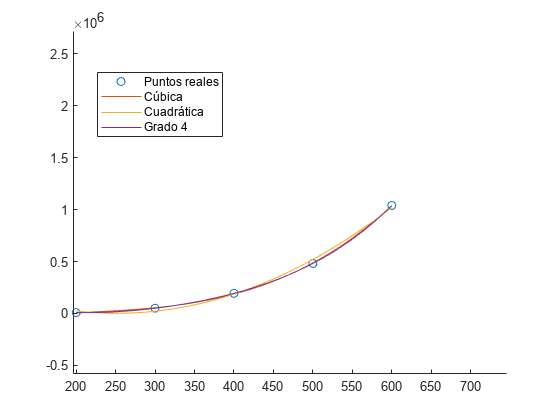

xlim([196 746])
ylim([-582311 2717689])
legend("Position", [0.17381,0.67341,0.22321,0.15595])

%plot(f);